data_root_dir = '/home/linux-pc/gh/V1-Visual-Cortex-Visualization/data/crcns-pvc1/crcns-ringach-data/';
neuro_root_dir = 'neurodata/ac1/';
movie_root_dir = 'movie_frames/movie000_000.images/';
current_movie = "movie000_000_000.jpeg";
current_neuro_data = "ac1_u004_000.mat";

load_img = strcat(data_root_dir, movie_root_dir, current_movie);

%if ~strcmp(str1, str2)
%    disp('Strings are different');
%end

imread(load_img);

neuro_str = strcat(data_root_dir, neuro_root_dir, current_neuro_data);

load(neuro_str);

## Total Number of Conditions

pepANA.no_conditions

ans = 120

## Arrival Times for electrodes in pepANA.elec_list

pepANA.listOfResults{1}.repeat{1}.data{13}

ans = 1×2 cell array
    {[0.3537 0.4543 0.6036 0.6780 1.0123 1.1758 1.1779 1.1914 1.4126 1.4425 1.5338 1.6866 1.9662 2.5828 2.9451 3.3012 3.7744 3.9322 4.0201 4.6491 4.6791 4.7038 4.7153 4.7283 4.7530 4.9453 5.0114 5.0702 5.1571 5.2284 5.2450 5.2530 5.2793 5.3124 5.4489 5.4555 5.5446 5.6120 5.6444 5.9074 5.9447 6.0529 6.1861 6.4447 6.4658 6.4674 6.5947 6.6364 6.7368 6.7395 6.7992 7.1861 7.2076 7.2251 7.4116 7.4175 7.4342 7.4409 7.7366 7.7383 7.7427 7.7602 7.7752 7.9908 7.9988 8.0911 8.1284 8.2868 8.2950 8.3093 8.6980 8.7073 8.7739 8.9820 8.9861 9.3858 9.4068 9.4084 9.4132 9.4214 9.4284 9.4361 9.4736 9.4948 11.3779 11.5023 11.5521 11.5728 12.3103 12.4606 12.6606 12.7947 12.7983 12.9645 13.7019 13.7352 13.8687 14.5684 14.5775 14.6017 14.6351 14.6436 14.8638 14.8761 15.2851 15.3940 15.4686 15.4931 15.7483 16.3330 16.3440 16.8394 17.2726 17.2844 17.3010 17.4568 17.4682 17.5766 17.7683 18.4053 18.7387 19.0184 19.0555 19.1096 19.2100 19.6099 19.8890 19.8935 19.9430 19.9933 20.5885 22.0093 2

## Detected Waveforms at that time (48 samples of waveform snippets) (contains spikes and noise bc of low threshold) (1.6ms sampled at 30kHz at int8 precision)

pepANA.listOfResults{1}.repeat{1}.data{1}{2}

ans = 48×573 int8 matrix
     0    -6    -2     3    -3    -8     3     0    10    -7    -2     4    -6     3    -5     8    -8    -8    -3   -11     4   -15    -3    -8     9     2    -6    -4    -8    -1    -7     0    -9    10    -6     5    -7    -9    16    -3    20    -1   -11     9     0    -9    -3     5    -5   -16
    -1    -3    -2     2    -1     1    -3    -3    -2    -4    -3     7    -7     1    -7     5    -3    -9     1    -5     2   -18    -6   -16    -2     5   -10    -1    -7     3   -10    -1    -9     0     0     7   -13   -10     4    -7    17    -3   -17    -2     4   -14    -9     9    -8   -19
     3    -3    -2     1    -1     8    -3    -5    -8    -2     4     6    -6    -5    -7     2    -4     0     2    -1     1   -13    -4   -14    -7     4   -12    -8     1     3    -6    -5    -7    -7     2     5   -14    -5     3     5    18     2   -12    -7     7    -7   -12     4    -7   -11
     1    -3    -3     1    -3     6     1    -6    -2    -3     1     3

(size(pepANA.listOfResults{1}.repeat{1}.data{1}{1}, 2) / 30000) * 1000

ans = 19.1000

## Electrodes

pepANA.elec_list

ans =      5     6    10    13    15    22    23    26    38    46    47    54    55    73    78    85


## Examining Waveforms

q = pepANA.listOfResults{1}.repeat{1}.data{13}{2};
% size(q(1, :));
% one_waveform = q(1, :);
% plot(one_waveform)

% fig_multiple_spikes_electrode13 = figure("Name", "Channel 13 Electrode");
% ax_multi_spikes_channel13 = axes("Parent", fig_multiple_spikes_electrode13);
% plot(ax_multi_spikes_channel13, q);

## SVD of Waveforms

condition = 1;
electrode = 13;


function mean_detected_signal = analyzeWaveform(condition, electrode, verbose)
    % Check if pepANA is in workspace
    if ~evalin('base', 'exist(''pepANA'', ''var'')')
        error('pepANA structure not found in the base workspace.');
    end

    if nargin < 3
        verbose = false;
    end

    % Get waveform from pepANA in base workspace
    pepANA = evalin('base', 'pepANA');
    
    % Extract waveform
    waveform = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{2};

    % Ensure waveform is in double precision
    waveform = double(waveform);

    % Perform SVD
    [~, ~, v] = svd(waveform);

    % Plot first two principal components
    if verbose
        fig1 = figure('Name', 'Original Waveforms', 'Position', [100, 100, 800, 600]);
        ax1 = axes('Parent', fig1);
        plot(ax1, v(:, 1), v(:, 2), '.', 'MarkerSize', 10);
        hold(ax1, 'on');
        plot(ax1, 0, 0, 'r.', 'MarkerSize', 25);
        xlabel(ax1, '1st Principal Component');
        ylabel(ax1, '2nd Principal Component');
        title(ax1, sprintf('SVD Projection: Condition %d, Electrode %d', condition, electrode));
        grid(ax1, 'on');
    end
        

    idx = kmeans(double(waveform'),2); %% cluster waveforms in 2 classes using k-means
    idx1 = find(idx==1); 
    idx2 = find(idx==2);
    if verbose
        fig2 = figure("Name", "SVD of Waveforms and Plot of a Waveform");
        ax3_1 = subplot(1, 2, 1, "Parent", fig2);
        plot(ax3_1, v(idx1, 1), v(idx1, 2), 'b.', 'markersize',10); 
        hold on;
        plot(ax3_1, 0, 0, 'r.', 'markersize', 25); 
        plot(ax3_1, v(idx2, 1), v(idx2, 2), 'g.', 'markersize', 10);
    
        ax3_2 = subplot(1, 2, 2, "Parent", fig2);
        errorbar(ax3_2, 1:size(waveform,1), mean(double(waveform(:, idx2)'),1), std(double(waveform(:, idx2)'),[],1), 'g'); 
        hold on;
        errorbar(ax3_2, 1:size(waveform,1), mean(double(waveform(:, idx1)'),1), std(double(waveform(:, idx1)'),[],1), 'b');
    
        xlim([0 49])
    end
    mean_detected_signal = mean(double(waveform(:, idx2)'),1);
end

signal = analyzeWaveform(1, 13)

signal =    -1.5556   -2.3704   -1.0741   -0.0741   -0.4074    0.9630    3.4444    1.3333  -13.0370  -41.1111  -61.7037  -54.7778  -32.4815  -10.9630    3.4074   13.7037   20.7778   27.2963   30.4815   29.7037   31.1481   32.7778   30.8148   28.7037   27.3333   25.5926   24.4444   21.4444   16.9259   14.7778   12.9630    8.5926    2.7407   -1.5185   -3.3333   -5.1481   -8.5556  -10.8889  -11.0000  -12.2222  -15.6667  -15.9630  -14.5556  -13.3333  -13.1481  -12.5926  -11.9630  -12.2593


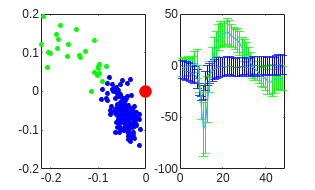



plot(signal)



waveform = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{2};

[u, s, v] = svd(double(q));
fig1 = figure('Name', 'Original Waveforms', "Position", [100, 100, 800, 600]);
ax1 = axes("Parent", fig1);
plot(ax1, v(:, 1), v(:, 2), '.', 'markersize', 10);
hold on;
plot(ax1, 0,0, 'r.', 'markersize', 25);

## Classifying Waveforms with K-means clustering

fig2 = figure("Name", "SVD of Waveforms and Plot of a Waveform");

idx = kmeans(double(q'),2); %% cluster waveforms in 2 classes using k-means
idx1 = find(idx==1); 
idx2 = find(idx==2);

ax3_1 = subplot(1, 2, 1, "Parent", fig2);
plot(ax3_1, v(idx1, 1), v(idx1, 2), 'b.', 'markersize',10); 
hold on;
plot(ax3_1, 0, 0, 'r.', 'markersize', 25); 
plot(ax3_1, v(idx2, 1), v(idx2, 2), 'g.', 'markersize', 10);

ax3_2 = subplot(1, 2, 2, "Parent", fig2)
errorbar(ax3_2, 1:size(q,1), mean(double(q(:, idx2)'),1), std(double(q(:, idx2)'),[],1), 'g'); 
hold on;
errorbar(ax3_2, 1:size(q,1), mean(double(q(:, idx1)'),1), std(double(q(:, idx1)'),[],1), 'b');

xlim([0 49])

% set(gcf, 'Renderer', 'painters'); % or 'opengl'

% waveform = pepANA.listOfResults{1}.repeat{1}.data{13}{2}(1, :)
% fig0 = figure("Name", "Single Waveform");
% ax0 = axes("Parent", fig0);
% plot(ax0, waveform);

% plot(ax0, pepANA.listOfResults{1}.repeat{1}.data{13}{1})

## Natural image sequences data:

% Indices of the movie frame that appeared 60ms before a spike 
c = 1 % condition
T = 3/90 % 3 frames (of the same image) at 90 Hz of the monitor (duration of each frame in seconds.)
spk = pepANA.listOfResults{c}.repeat{1}.data{13}{1};
spk = spk - 60e-3; % frames 60 ms before a spike sample
frame_idx = floor(spk/T);
frame_idx

frame_idx(1);
n_prefix_frame_zeros = 3 - (floor(log10(frame_idx(1))) + 1)

## Getting the frames

movie_id = pepANA.listOfResults{120}.values(1);
segment_id = pepANA.listOfResults{120}.values(2);

n_prefix_zeros = 3 - (floor(log10(segment_id{1})) + 1)
prefix_zeros_segment_id = sprintf('%s', repmat("0", 1, n_prefix_zeros));

% Indices of the movie frame that appeared 60ms before a spike 
c = 1 % condition
T = 3/90 % 3 frames (of the same image) at 90 Hz of the monitor (duration of each frame in seconds.)
spk = pepANA.listOfResults{c}.repeat{1}.data{13}{1};
spk = spk - 60e-3; % frames 60 ms before a spike sample
frame_idx = floor(spk/T);

% Create the string to show the image that is the stimulus to the detected spike
n_prefix_frame_zeros = 3 - (floor(log10(frame_idx(1))) + 1);
prefix_zeros_frame_idx = sprintf('%s', repmat("0", 1, n_prefix_frame_zeros))
movie_image_string = "movie00" + int2str(movie_id{1}) + "_" + prefix_zeros_segment_id + int2str(segment_id{1}) + "_" + prefix_zeros_frame_idx + int2str(frame_idx(1)) + ".jpeg"
movie_image_dir = data_root_dir + "movie_frames/" + "movie00" + int2str(movie_id{1}) + "_" + prefix_zeros_segment_id + int2str(segment_id{1}) + ".images/"
image_path = strcat(movie_image_dir, movie_image_string);
img = imread(image_path);
imshow(img)